% Define file path (Update with your actual file location)
filepath = "C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv"

filepath = "C:\Users\dhiid\OneDrive\Desktop\Matlab simulations\tracking_data.csv"


% Read the CSV file into a table
data = readtable(filepath);
% Display first few rows to check structure
disp(data(1:5, :));

     Var1      Var2     Var3    Var4    Var5    Var6    Var7 
    _______    _____    ____    ____    ____    ____    _____

    0.18554    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.22273    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.24087    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.28597    -7.24    9.38    -7.8    6.82    -100    -66.7
    0.33716    -7.24    9.38    -7.8    6.82    -100    -66.7



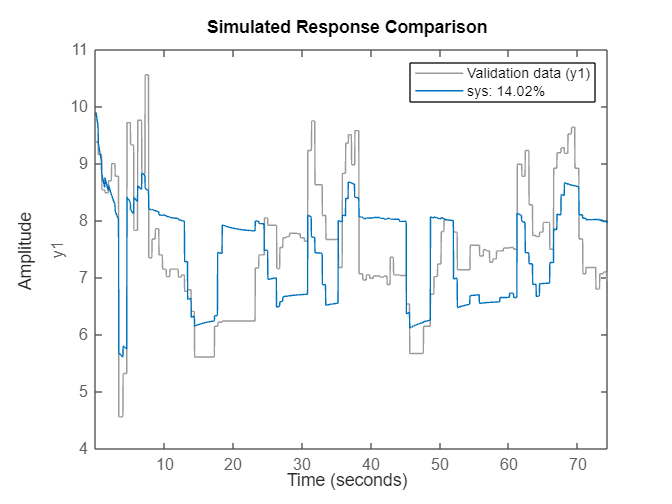


% Extract data (modify column indices if necessary)   
t=data{2,1}-data{1,1};
x1 = data{:,2}; 
y1= data{:,3};
x2 = data{:,4}; % Current X values (actual system output)
y2 = data{:, 5}; % Desired X values (setpoint)

% Generate time (or sample index) for the system (assume unit time step)
numSamples = length(x1);

% Create input-output data for system identification (assumes x1 is output and x2 is input)
inputData = [y2]; % Setpoint is the input
outputData = [y1]; % System output is the observed x1

% System Identification: Create an iddata object
sysData = iddata(outputData, inputData, t); % Sample time = 1 (unit time steps)

% Estimate a transfer function (using system identification)
sys = tfest(sysData,1,1); % Estimate a second-order transfer function model 

compare(sysData,sys);


% figure;
% pzmap(sys);
% grid on;
% title('Pole-Zero Map (s-Plane)');
% xlabel('Real Axis (\sigma)');
% ylabel('Imaginary Axis (j\omega)'); 
% 
% step(sys);  

% info = stepinfo(sys);
% disp(info);  

pidTuner(sys,'PID');

% Use PID Tuner to tune PID controller for the identified system
%pidController = pidTuner(sys, 'pid'); 



